# Create and Customize Pseudocolor Plots

`pcolor` creates a pseudocolor plot that displays matrix data as an array of colored cells (known as *faces*). MATLAB® creates this plot as a flat surface in the *x*-*y* plane. 

### Create Surface Data

We can generate the MATLAB logo, which is the L-shaped membrane using the built-in function `membrane(k),` the k-th eigenfunction of the L-shaped membrane. Select an eigenfunction to visualize.

eigenfunction = 2;
L = 100*membrane(eigenfunction,100);

### Basic Pseudocolor Plot

Visualize the L-shape membrane using `pseudocolor`.

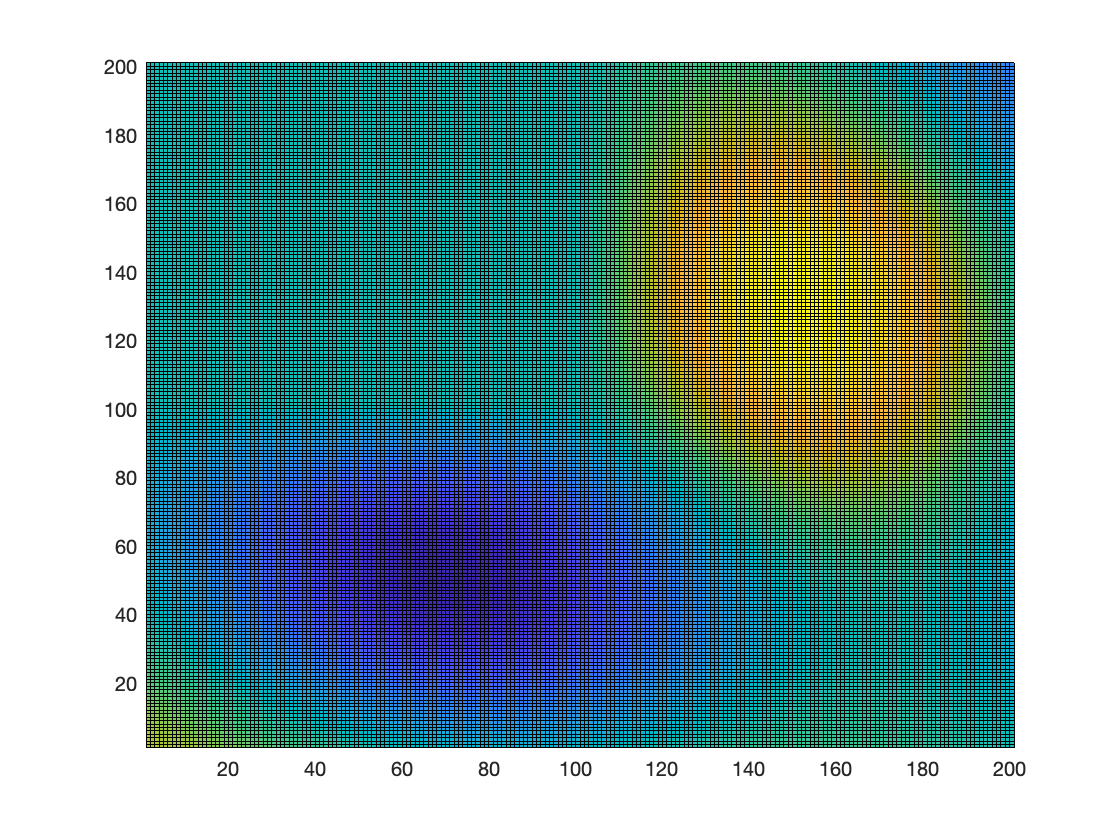

pcolor(L);

## Customization

### Smooth Out Coloring

Remove lines from the plot by setting the *EdgeColor* property of the Surface object to *none.* Change the default shading to interpolate the colormap across the plot.

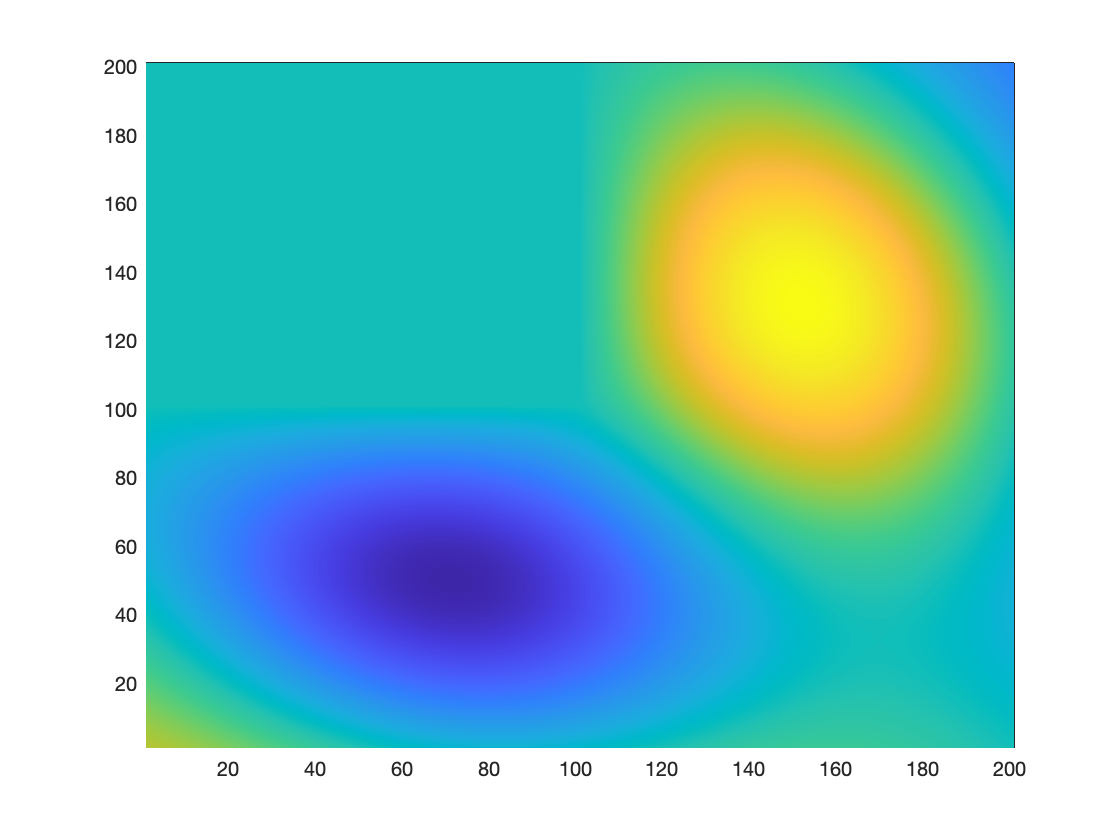

p = pcolor(L);
p.EdgeColor = "none";         % Remove lines from the plot
shading interp    % Specify the shading method to use

### Change Chart Colormap

There are several default colormaps specified in MATLAB, some are shown in the drop down menu. Specify a different colormap to use in `pcolor`. Add a colorbar as a legend to understand depth data.

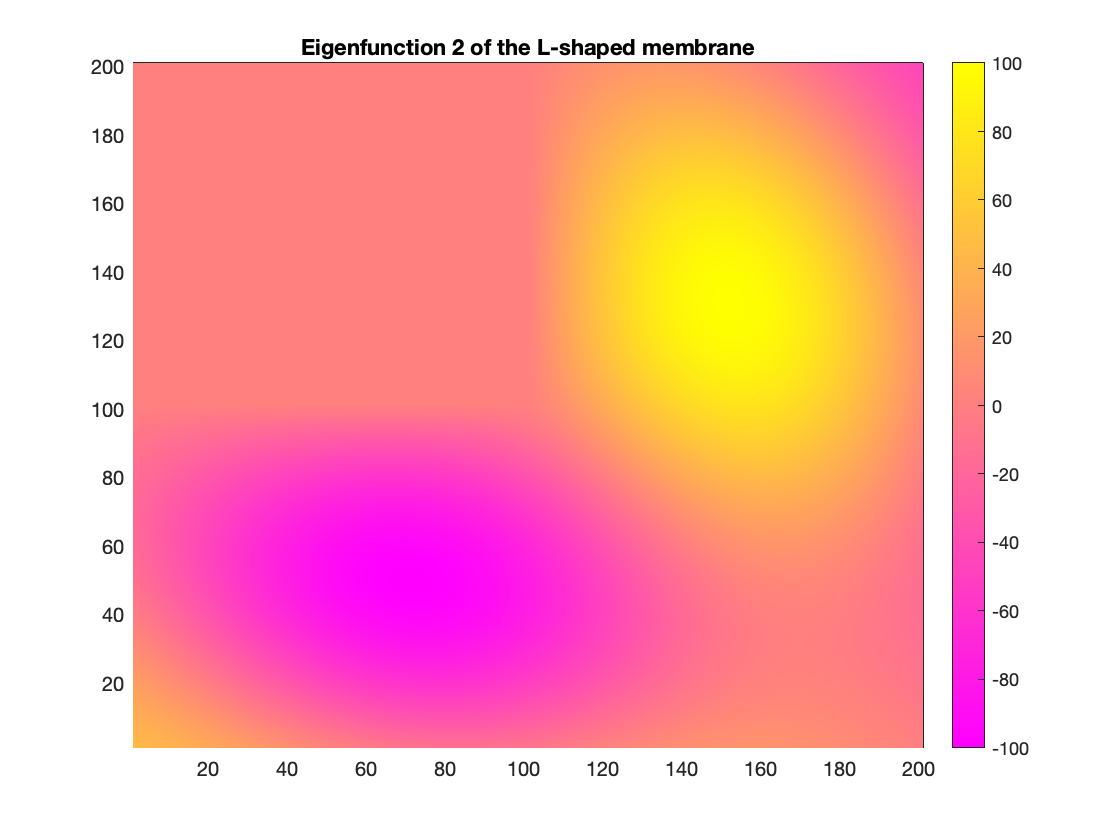

colormap("spring"); % Specify colormap
title(sprintf("Eigenfunction %d of the L-shaped membrane",...
    eigenfunction))
colorbar

## **Additional Information**

### **Get All Surface Properties **

Graphics objects in MATLAB have many properties. To see all the properties of a Surface, uncomment the following code. View or modify these properties using dot notation.

% get(p)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[pseudocolor](https://www.mathworks.com/help/matlab/ref/pcolor.html?searchHighlight=pcolor&s_tid=srchtitle)

Copyright (c) 2021, The MathWorks, Inc.